**Operators**

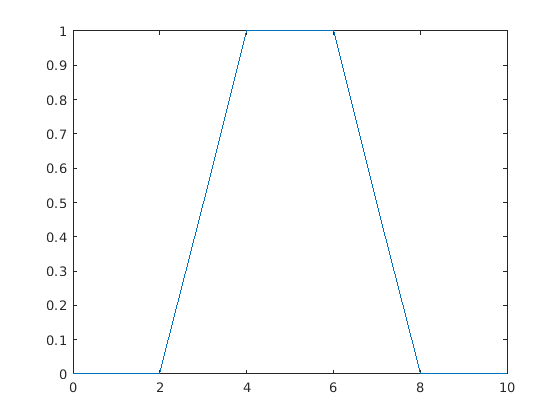

fuz_one_mem =          0         0         0    0.5000    1.0000    1.0000    1.0000    0.5000         0         0         0


% Set of possible values
G= 0:10;
% Fuzzy set one membership function
fuz_one_mem= fuz_mem(G, 0.5, -0.5, 2, 8, 4, 6);
plot(G, fuz_one_mem);

**Intersection**

function out= fuz_mem(set, up_slope, down_slope, supp_start, supp_end, core_start, core_end)
% Trapeziodal Membership Function
% set: array of possible member values
% up_slope: slope of ramping up
% down_slope: slope of ramping down
% supp_start: Start of Fuzzy Set Support (out != 0)
% supp_end: End of Fuzzy Set Support
% core_start: Start of Fuzzy Set Core (out == 1)
% core_end: End of Fuzzy Set Core

% Initialize output
out= zeros(1,length(set));

% indices
supp_start_idx= find(set==supp_start);
supp_end_idx= find(set==supp_end);
core_start_idx= find(set==core_start);
core_end_idx= find(set==core_end);

for idx= 1:length(set)
    if idx < supp_start_idx
        % Zero level
        out(idx)= 0;
    end
    if idx >= supp_start_idx && idx < core_start_idx
        % Ramp up
        out(idx)= up_slope*(idx-supp_start_idx);
    end
    if idx >= core_start_idx && idx < core_end_idx
        % Core of Fuzzy set
        out(idx)= 1;
    end
    if idx >= core_end_idx && idx < supp_end_idx
        % Ramp down
        out(idx)= 1+ down_slope*(idx-core_end_idx);
    end
    if idx >= supp_end_idx
        % Zero level
        out(idx)= 0;
    end
end

end